# Import file

clear all
close all
clc

 DFS_ = importfile("Data/DFS.N.csv");    %Discover Financial Services
 GWW_ = importfile("Data/GWW.N.csv");    %Grainger Inc.
 NI_ = importfile("Data/NI.N.csv");      %Nisource
 FSLR_ = importfile("Data/FSLR.OQ.csv"); %First Solar 
 VZ_ = importfile("Data/VZ.N.csv");      %Verizon
 SPX_ = importfile("Data/SPX.csv");      %Standard and Poor 500

## 0 Data Preprocessing

Data cleaning

 %1) Seleziono le osservazioni dai primi dati utili
 Start_date = "2007-07-31T00:00:00Z";
 index = find(DFS_.Date == Start_date,1);
 date = datetime(DFS_.Date(index:end), 'InputFormat', 'yyyy-MM-dd''T''HH:mm:ss''Z''', 'Format', 'dd-MMM-yyyy');

 %(1)DFS
 index = find(DFS_.Date == Start_date,1);
 DFS = DFS_(index:end,:);
 
 %(2)GWW
 index = find(GWW_.Date == Start_date,1);
 GWW = GWW_(index:end,:);
 
 %(3)NI
 index = find(NI_.Date == Start_date,1);
 NI = NI_(index:end,:);
 
 %(4)FSLR
 index = find(FSLR_.Date == Start_date,1);
 FSLR = FSLR_(index:end,:);
 
 %(5)VZ
 index = find(VZ_.Date == Start_date,1);
 VZ = VZ_(index:end,:);
 
 %SPX
 index = find(SPX_.Date == Start_date,1);
 SPX = SPX_(index:end,"MonthTotalReturn");

 %Normalizzo i dati dei prezzi e plotto
n_SPX = (SPX.MonthTotalReturn - min(SPX.MonthTotalReturn))./(max(SPX.MonthTotalReturn)-min(SPX.MonthTotalReturn));
n_DFS = (DFS.PriceClose - min(DFS.PriceClose))./(max(DFS.PriceClose)-min(DFS.PriceClose));
n_FSLR = (FSLR.PriceClose - min(FSLR.PriceClose))./(max(FSLR.PriceClose)-min(FSLR.PriceClose));
n_GWW = (GWW.PriceClose - min(GWW.PriceClose))./(max(GWW.PriceClose)-min(GWW.PriceClose));
n_NI = (NI.PriceClose - min(NI.PriceClose))./(max(NI.PriceClose)-min(NI.PriceClose));
n_VZ = (VZ.PriceClose - min(VZ.PriceClose))./(max(VZ.PriceClose)-min(VZ.PriceClose));

%Plot Prezzi titoli e spx normalizzati
fig1 = figure('Position', [100, 100, 1600, 800])

fig1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 1600 800]
       Units: 'pixels'

  Show all properties


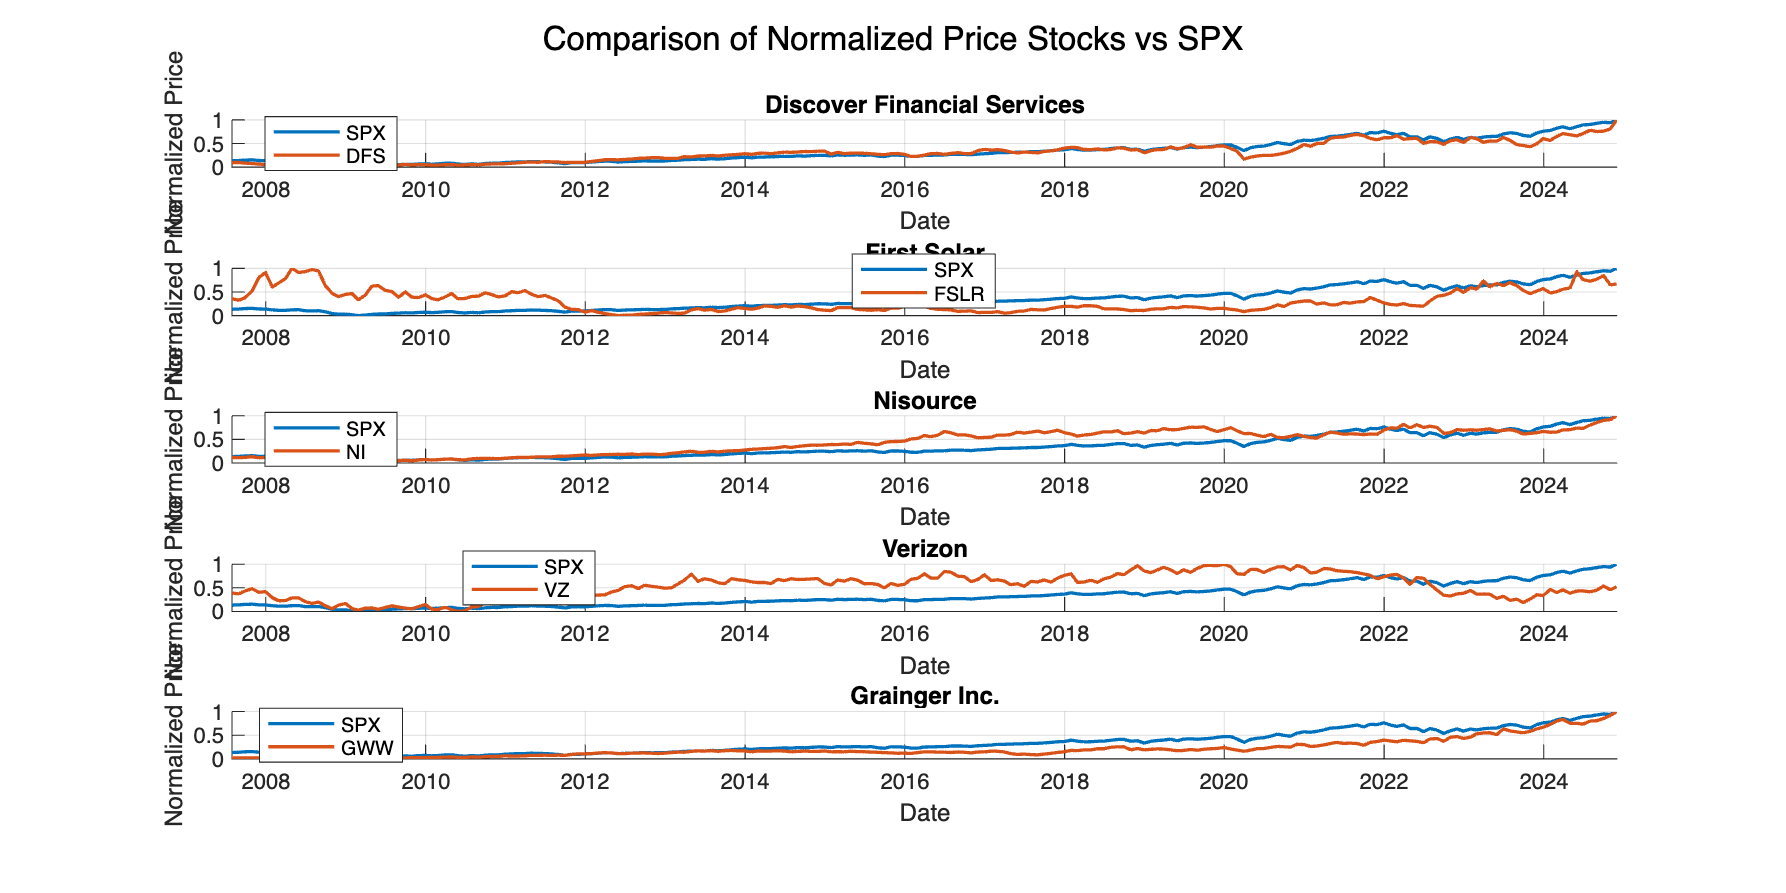

subplot(5,1,1)
hold on 
plot(date, n_SPX,"LineWidth",1.5)
plot(date, n_DFS,"LineWidth",1.5)
xlabel('Date');
ylabel('Normalized Price');
title('Discover Financial Services');
legend({'SPX','DFS'}, 'Location', 'best');
grid on;
subplot(5,1,2)
hold on 
plot(date, n_SPX,"LineWidth",1.5)
plot(date, n_FSLR,"LineWidth",1.5)
xlabel('Date');
ylabel('Normalized Price');
title('First Solar');
legend({'SPX','FSLR'}, 'Location', 'best');
grid on;
subplot(5,1,3)
hold on 
plot(date, n_SPX,"LineWidth",1.5)
plot(date, n_NI,"LineWidth",1.5)
xlabel('Date');
ylabel('Normalized Price');
title('Nisource');
legend({'SPX','NI'}, 'Location', 'best');
grid on;
subplot(5,1,4)
hold on 
plot(date, n_SPX,"LineWidth",1.5)
plot(date, n_VZ,"LineWidth",1.5)
xlabel('Date');
ylabel('Normalized Price');
title('Verizon');
legend({'SPX','VZ'}, 'Location', 'best');
grid on;
subplot(5,1,5)
hold on 
plot(date, n_SPX,"LineWidth",1.5)
plot(date, n_GWW,"LineWidth",1.5)
xlabel('Date');
ylabel('Normalized Price');
title('Grainger Inc.');
legend({'SPX','GWW'}, 'Location', 'best');
grid on;
sgtitle('Comparison of Normalized Price Stocks vs SPX');

saveas(fig1,"img/Price Stocks vs SPX.png")

## 0.1 Raccolta dati

%Estraggo dal dataset i dati che utilizzeremo per i vari calcoli
%raggruppandoli in matrici

adj_close = [DFS.PriceClose,GWW.PriceClose,NI.PriceClose,FSLR.PriceClose,VZ.PriceClose];
tot_returns = [DFS.MonthTotalReturn,GWW.MonthTotalReturn,NI.MonthTotalReturn,FSLR.MonthTotalReturn,VZ.MonthTotalReturn];
market_cap = [DFS.CompanyMarketCap,GWW.CompanyMarketCap,NI.CompanyMarketCap,FSLR.CompanyMarketCap,VZ.CompanyMarketCap];
n_stock = size(tot_returns,2);
spx_returns = table2array(diff(SPX)./SPX(2:end,1));
returns = tot_returns/100;

## 0.2 Test di distribuzione normale dei simple retunr (tot_returns)

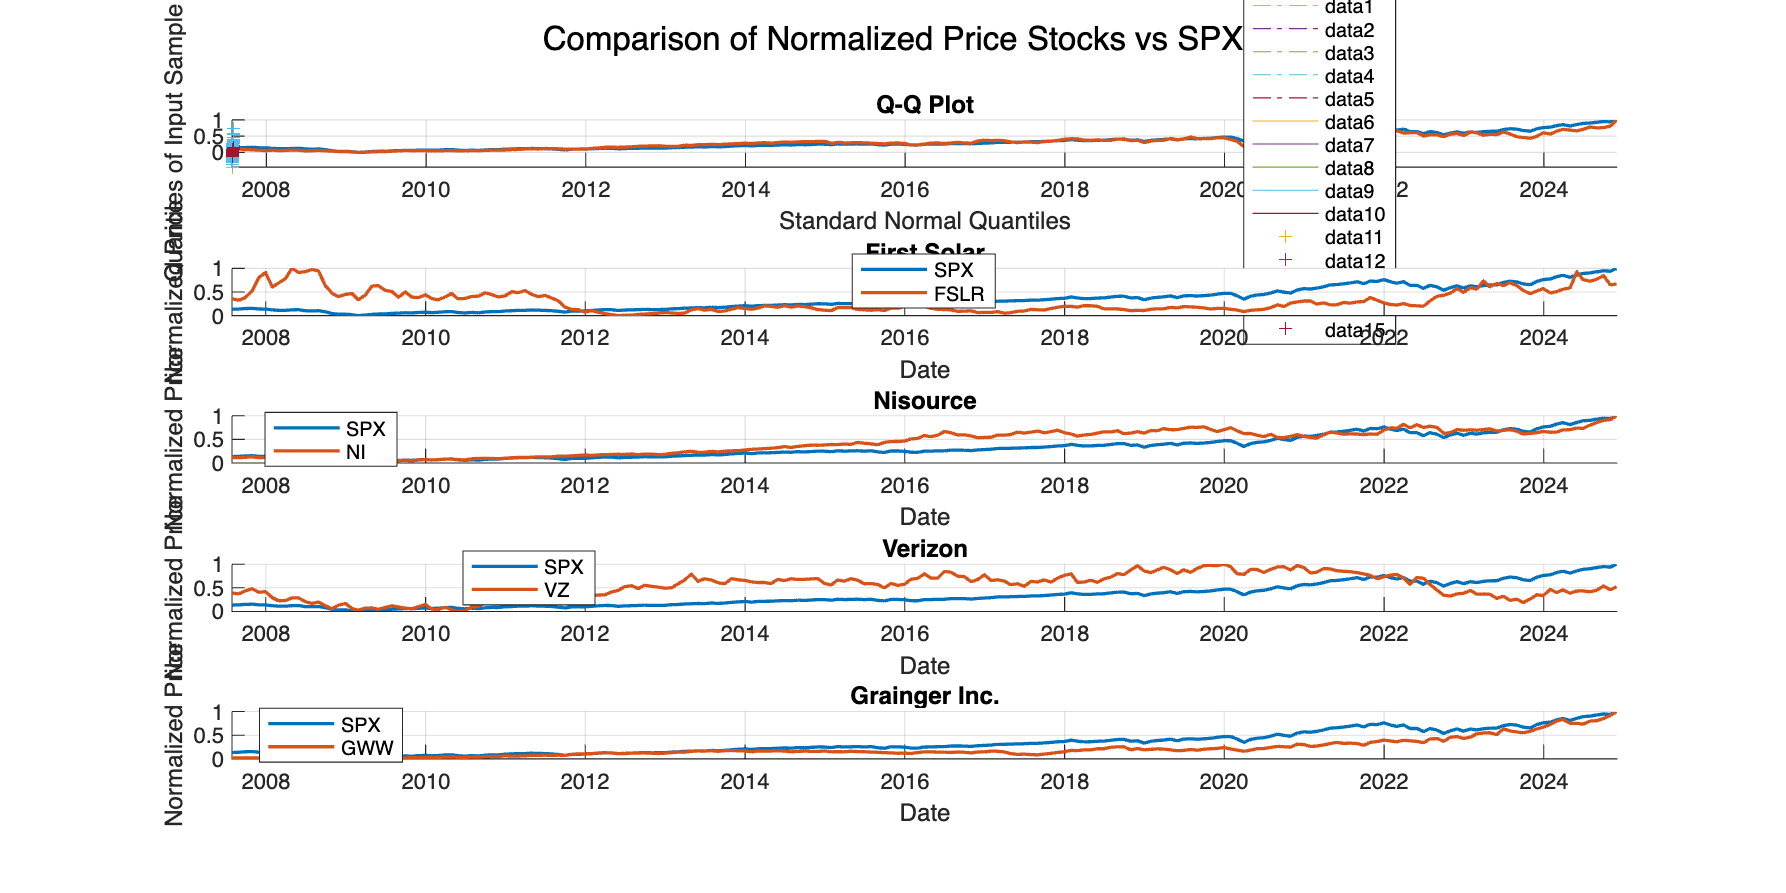

titoli = {'DFS', 'GWW', 'NI', 'FSLR' ,'VZ'};
qqplot(returns)
title('Q-Q Plot');
grid on;

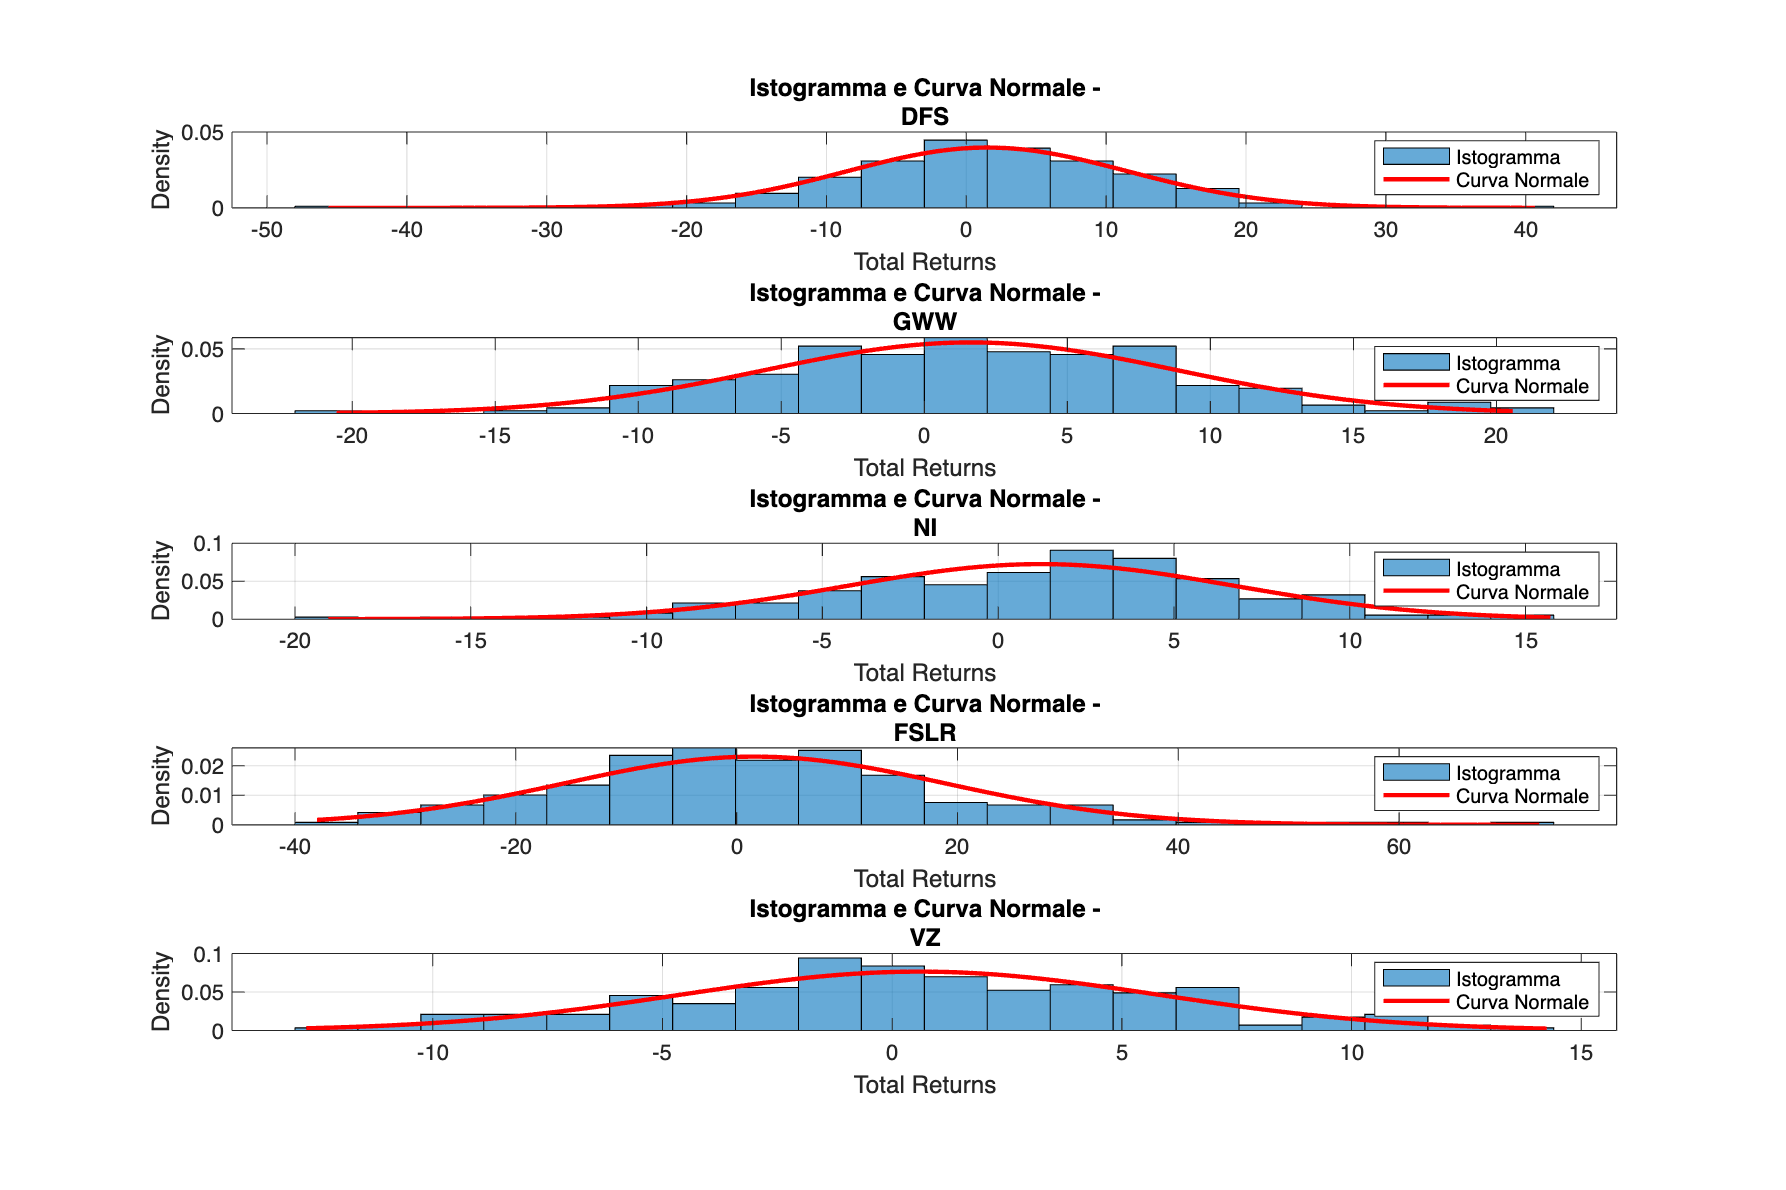


figure('Name', 'Distribuzione Total Rexturns', 'Position', [100, 100, 1200, 800]);
for i =1:1:5
    [H_0(i), pValue(i)] = jbtest(tot_returns(:,i));
    [H_log0(i), pValue(i)] = jbtest(returns(:,i));
    [H_0s(i), pValue(i)] = swtest(tot_returns(:,i));
    [H_log0s(i), pValue(i)] = swtest(returns(:,i));

    %Istogramma Simple Return
    subplot(5,1,i)
    histogram(tot_returns(:,i), 20, 'Normalization', 'pdf');
    hold on
    x = linspace(min(tot_returns(:,i)), max(tot_returns(:,i)), 100);
    pdf_normal = normpdf(x, mean(tot_returns(:,i)), std(tot_returns(:,i)));
    plot(x, pdf_normal, 'r', 'LineWidth', 2);
    hold off
    title(['Istogramma e Curva Normale -' titoli(i)]);
    xlabel('Total Returns');
    ylabel('Density');
    legend({'Istogramma', 'Curva Normale'});
    grid on;
end

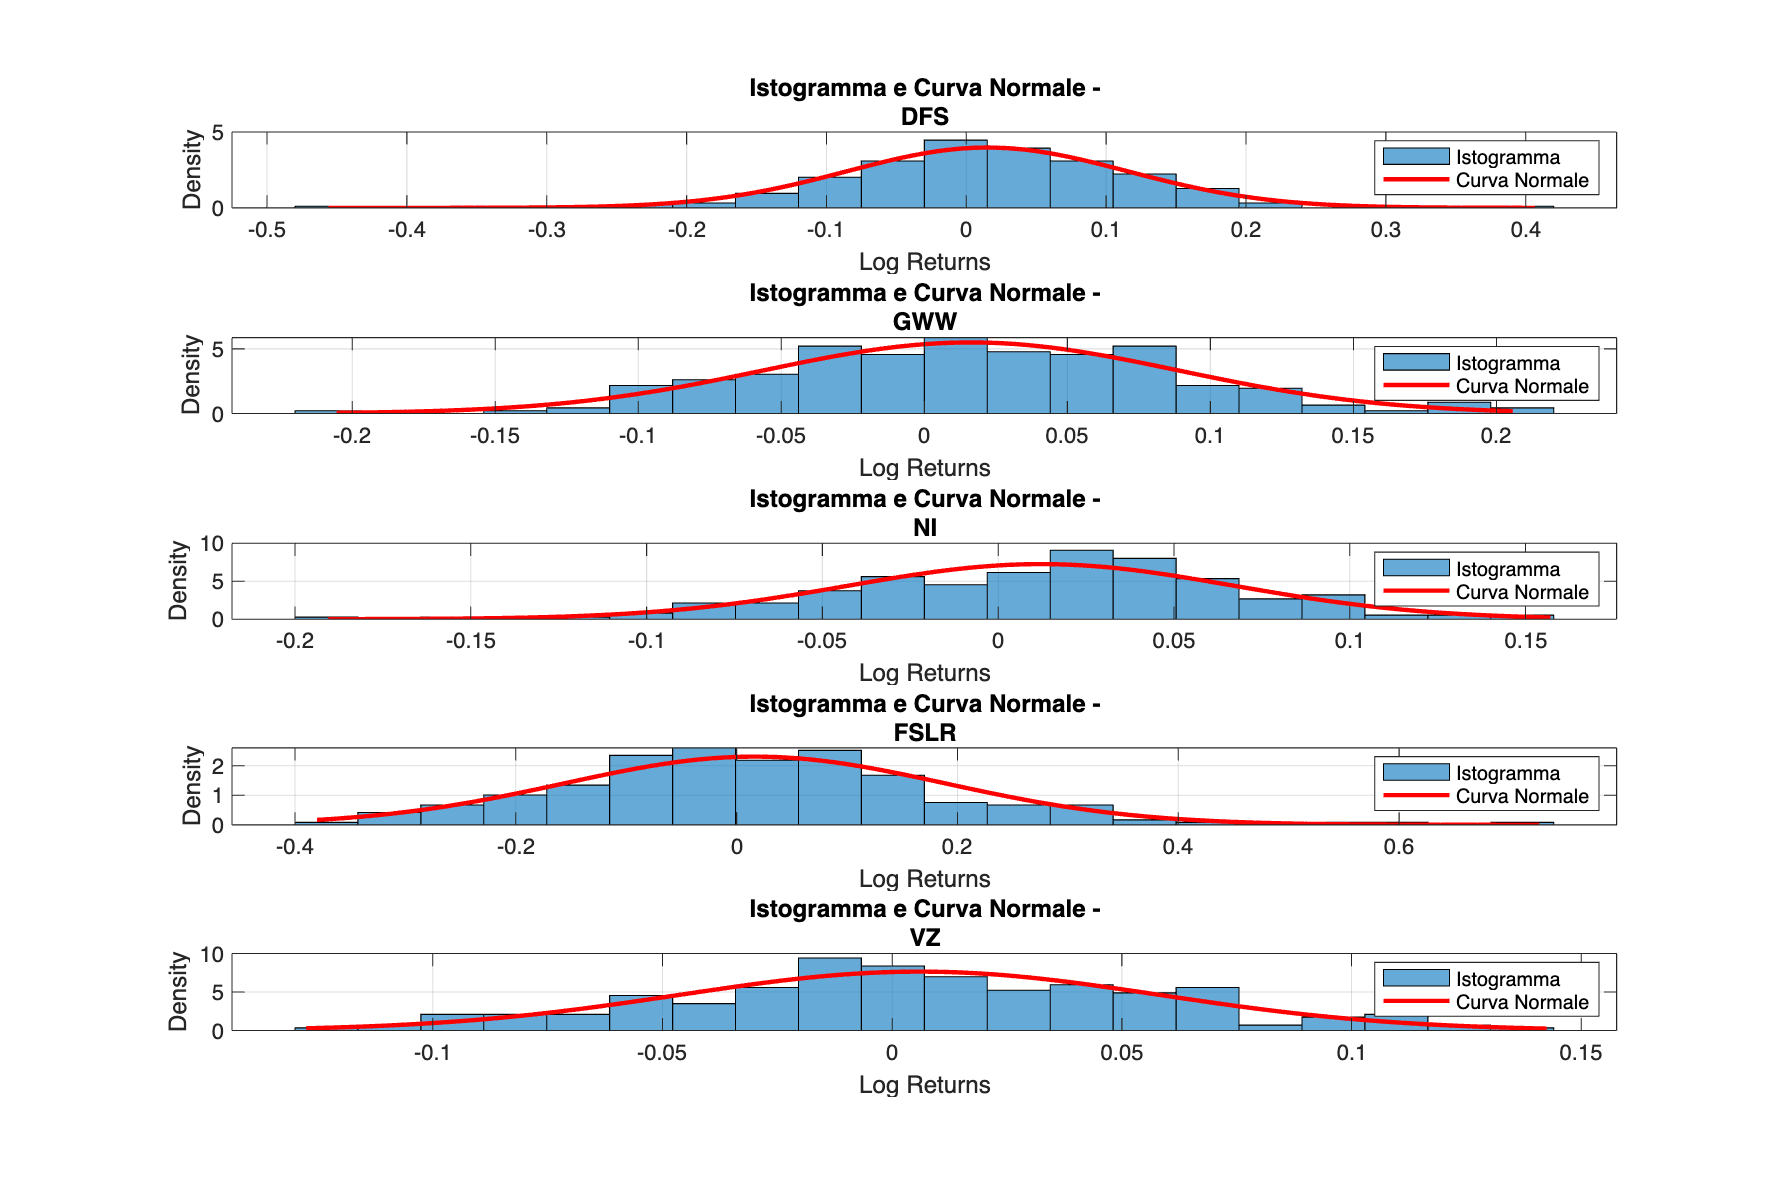


figure('Name', 'Distribuzione Log Returns', 'Position', [100, 100, 1200, 800]);
for i=1:1:5
    %Log Return sul total returns
    subplot(5,1,i)
    histogram(returns(:,i), 20, 'Normalization', 'pdf');
    hold on;

    x = linspace(min(returns(:,i)), max(returns(:,i)), 100);
    pdf_normal = normpdf(x, mean(returns(:,i)), std(returns(:,i)));
    plot(x, pdf_normal, 'r', 'LineWidth', 2);
    hold off;
    title(['Istogramma e Curva Normale -' titoli(i)]);
    xlabel('Log Returns');
    ylabel('Density');
    legend({'Istogramma', 'Curva Normale'});
    grid on;
end

## 0.3 Plot Log/Simple return

fig2 = figure('Position',[100,100,1600,1000])

fig2 =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 1600 1000]
       Units: 'pixels'

  Show all properties


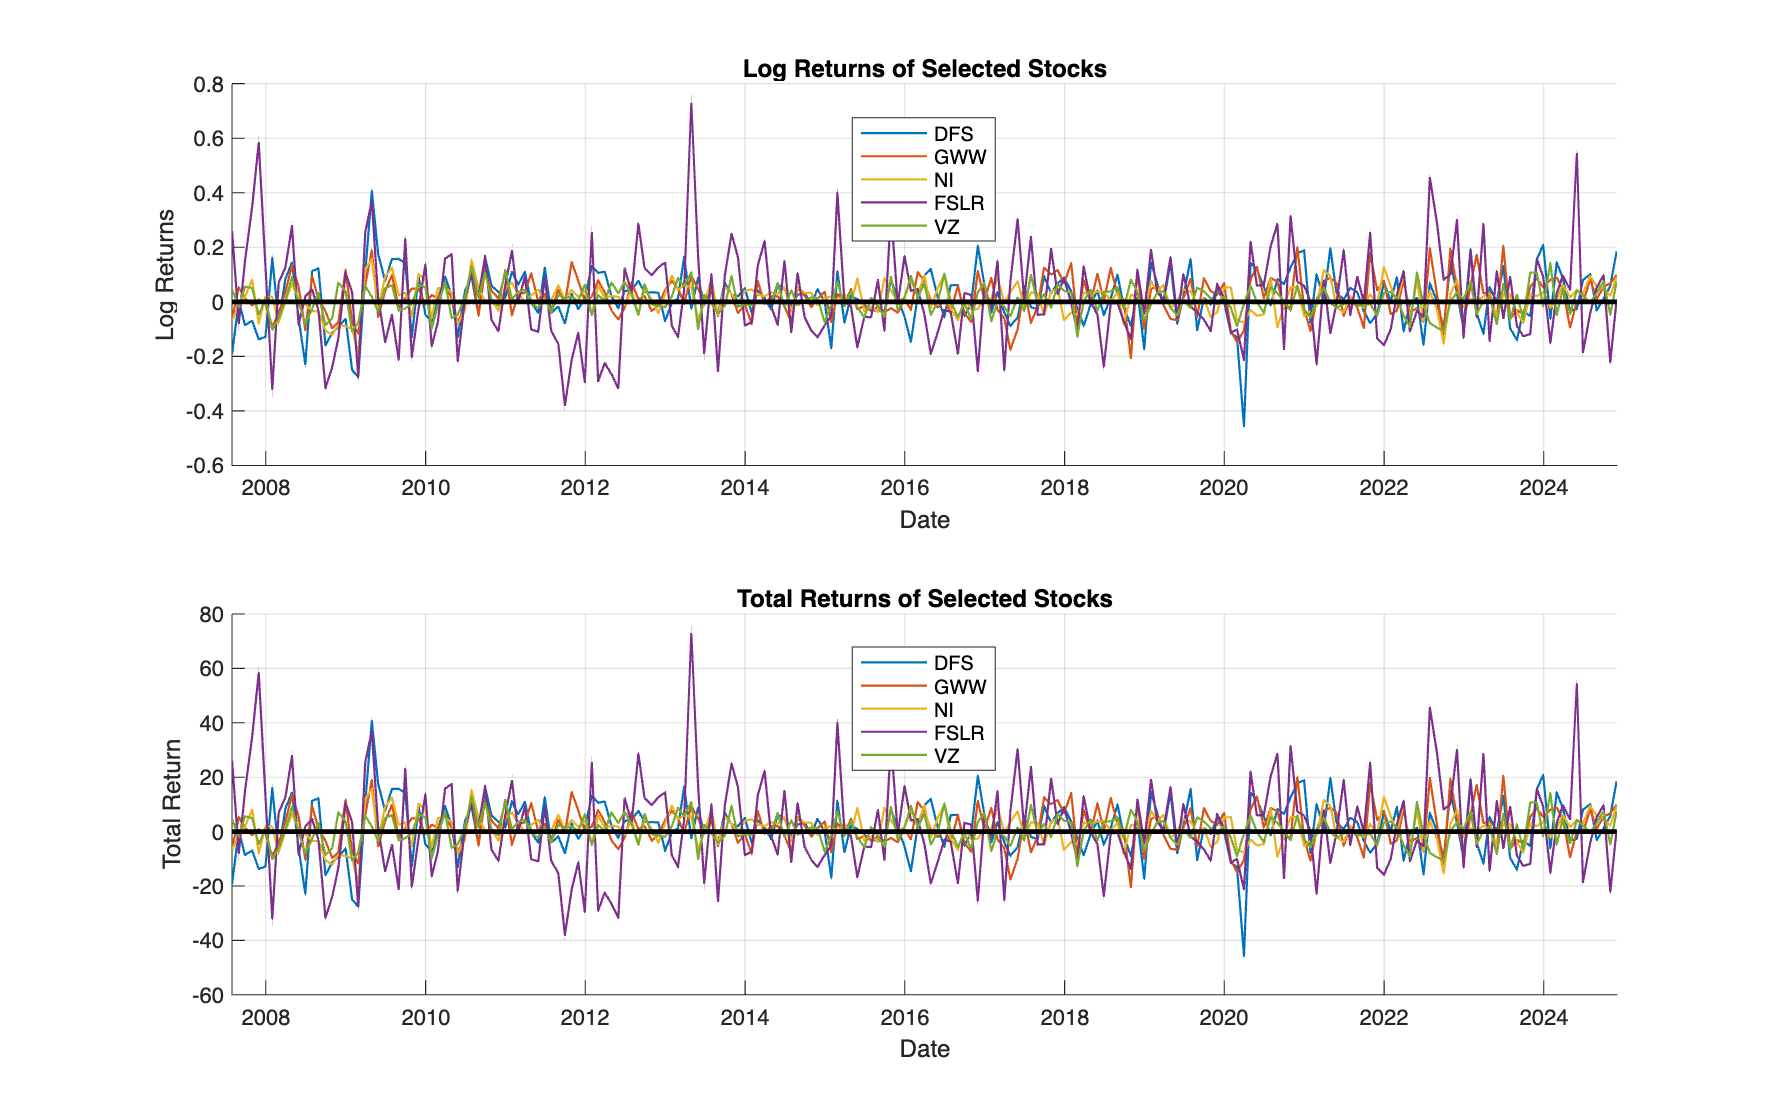

subplot(2,1,1)
hold on
plot(date, returns(:,1),"LineWidth",1)
plot(date, returns(:,2),"LineWidth",1)
plot(date, returns(:,3),"LineWidth",1)
plot(date, returns(:,4),"LineWidth",1)
plot(date, returns(:,5),"LineWidth",1)
plot(date,zeros(size(returns(:,1))),LineWidth=2.2,Color="k")
xlabel('Date');
ylabel('Log Returns');
title('Log Returns of Selected Stocks');
legend({'DFS', 'GWW', 'NI', 'FSLR' ,'VZ'}, 'Location', 'best');
grid on;
subplot(2,1,2)
hold on 
plot(date, tot_returns(:,1),"LineWidth",1)
plot(date, tot_returns(:,2),"LineWidth",1)
plot(date, tot_returns(:,3),"LineWidth",1)
plot(date, tot_returns(:,4),"LineWidth",1)
plot(date, tot_returns(:,5),"LineWidth",1)
plot(date,zeros(size(returns(:,1))),LineWidth=2.2,Color="k")
xlabel('Date');
ylabel('Total Return');
title('Total Returns of Selected Stocks');
legend({'DFS', 'GWW', 'NI', 'FSLR' ,'VZ'}, 'Location', 'best');
grid on;

saveas(fig2,"img/Total and Log returns.png")

## 1 Stima dei valori di matrice di covarianza e rendimenti attesi (calcolati come media)

mu = mean(returns)';               %vettore rendimenti attesi deve essere un vettore colonna
sigma = cov(returns);

## 1.1 Constant Correlation Approach

cor = corr(returns);                                                       %Matrice di correlazione
rho = sum(sum(cor - eye(n_stock)))/(n_stock*(n_stock-1));                  %Valor medio di correlazione
vola = diag(sqrt(diag(sigma)));                                            %Volatilità diagonale mtx covarianza  
cor_CC = rho+eye(n_stock)*(1-rho);                                         %Mtx di costruzione per avere 1 in diagonale e rho su non diag
sigma_CC = vola*cor_CC*vola;

## 1.2 Shrinkage Estimation

lambda = 0.02;
k = 0.35;
sigma_shr = (1-k)*sigma+k*(sigma_CC);
t = 1:length(returns);
mu_exp = sum(returns.*exp(-lambda*(t-length(returns)))')'/sum(exp(-lambda*(t-length(returns)))); %Media pesata su un fattore esponenziale temporale decrescente

## 1.3 Plot delle matrici sigma, sigma_constant correlation, sigma_shrinkage e dei rendimenti semplici ed esponenziali

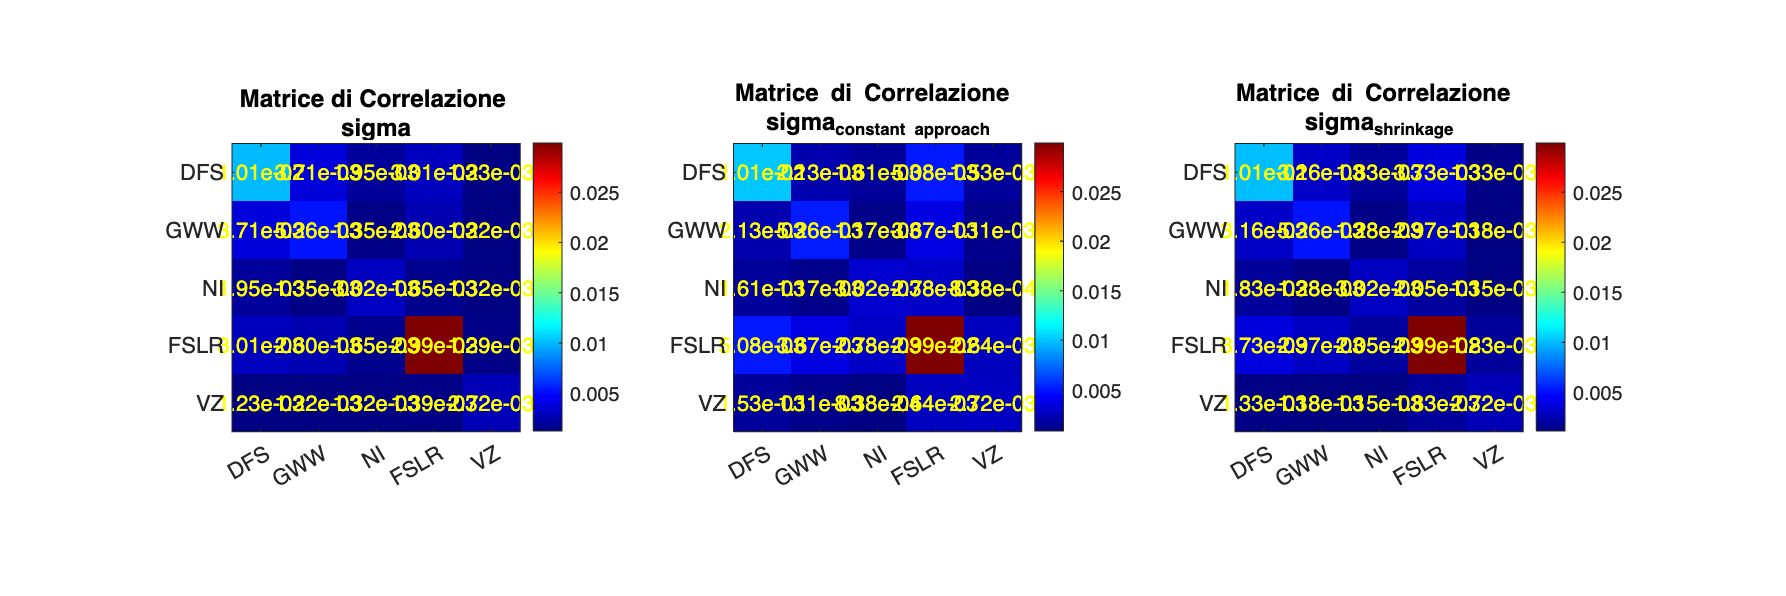

cor_mtx = {sigma, sigma_CC, sigma_shr};
name_mtx = {'sigma','sigma_{constant approach}','sigma_{shrinkage}'};
cmap = jet; 

fig3 = figure('Position', [100, 100, 1800, 600]); 
for i = 1:length(cor_mtx)
    subplot(1, length(cor_mtx), i);        
    imagesc(cor_mtx{i});               
    colormap(cmap);
    colorbar;                              
    clim([min(cor_mtx{i},[],'all') max(cor_mtx{i},[],'all')]);                         
    title(['Matrice di Correlazione ', name_mtx(i)]);
    xticks(1:length(titoli));              
    yticks(1:length(titoli));
    xticklabels(titoli);                  
    yticklabels(titoli);
    axis square;                           

    for row = 1:size(cor_mtx{i}, 1)
        for col = 1:size(cor_mtx{i}, 2)
            value = cor_mtx{i}(row, col);     
            text(col, row, sprintf('%.2e', value),'HorizontalAlignment', 'center','Color', 'yellow','FontSize', 10);                     
        end
    end
end

fig4 = figure('Position', [100, 100, 900, 300]);
bar_data = [mu, mu_exp];
bar(bar_data);
xticks(1:length(titoli)); 
xticklabels(titoli); 
legend({'Media Semplice', 'Media Esponenziale'}, 'Location', 'best');
xlabel('Stock');
ylabel('Rendimento Medio');
title('Confronto tra Media Semplice e Media Esponenziale');
grid on;

saveas(fig3,"img/HeatMap_variance_mtx.png")

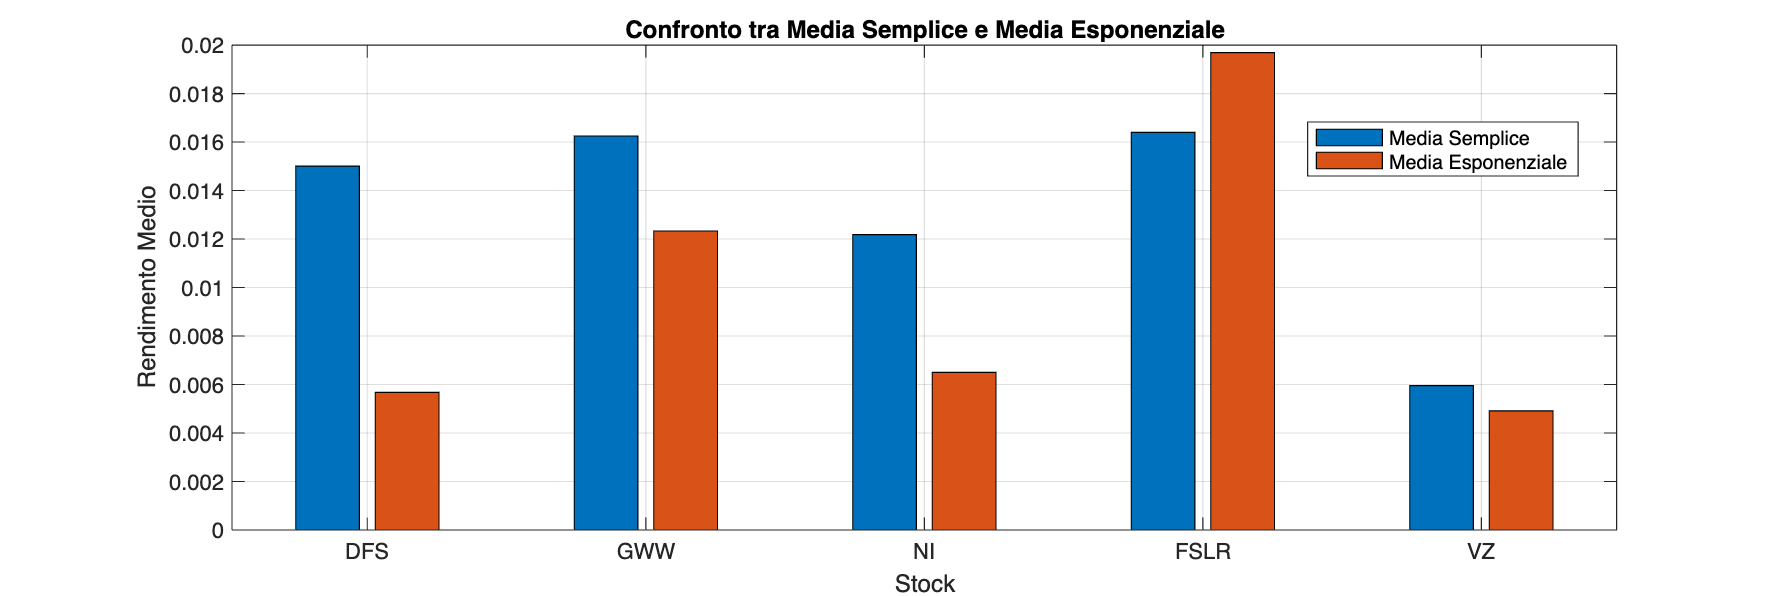

saveas(fig4,"img/Rendimenti_classic_log.png")

## 1.4 Calcolo delle variabili mu,sigma,A,B,C,D

% Markowitz con sigma e mu teorici
[g,h,A,B,C,D] = MK(mu,sigma)

g =    -0.0093
   -0.4343
   -0.1352
   -0.0533
    1.6321


h =     1.3631
   59.5193
   49.7717
    6.2188
 -116.8730


A = 5.1516

B = 0.0758

C = 513.7562

D = 12.3794


% Esempio portafolgio ugualmente distribuito ed ottimizzato secondo MK
w_equo = 1/n_stock.*ones(n_stock,1);  %Portafolgio equamente distribuito
variance_equo = w_equo'*sigma*w_equo; %Varianza portafolgio equamente distribuito
mu_equo = w_equo'*mu;                 %Rendimento portafolgio equamente distribuito 

w_opt = g+h*mu_equo;                  %Portafolgio ottimizzato con target il rendimento dell'equally
variance_opt = w_opt'*sigma*w_opt;    %Varianza ottimizzata con pesi per rendimento equally

## 1.5 Calcolo della frontiere con Sigma valutato tramite il Correlation Constant Approach

target_mu = mu_equo;
[g_cc,h_cc,A_CC,B_CC,C_CC,D_CC] = MK(mu,sigma_CC);
w_CC = g_cc+h_cc*target_mu

w_CC =     0.0876
    0.3521
    0.4865
   -0.0233
    0.0970


variance_CC = w_CC'*sigma*w_CC;

## 1.6 Calcolo della frontiere con Sigma valutato tramite il Shrinkage Approach

target_mu = mu_equo;
[g_shr,h_shr,A_shr,B_shr,C_shr,D_shr] = MK(mu,sigma_shr);
w_shr = g_shr+h_shr*target_mu

w_shr =     0.0371
    0.3468
    0.5084
    0.0127
    0.0950


variance_shr = w_shr'*sigma*w_shr;

## 1.7 Plot dei pesi di portafolgio per lo stesso valore target (mu_equo)

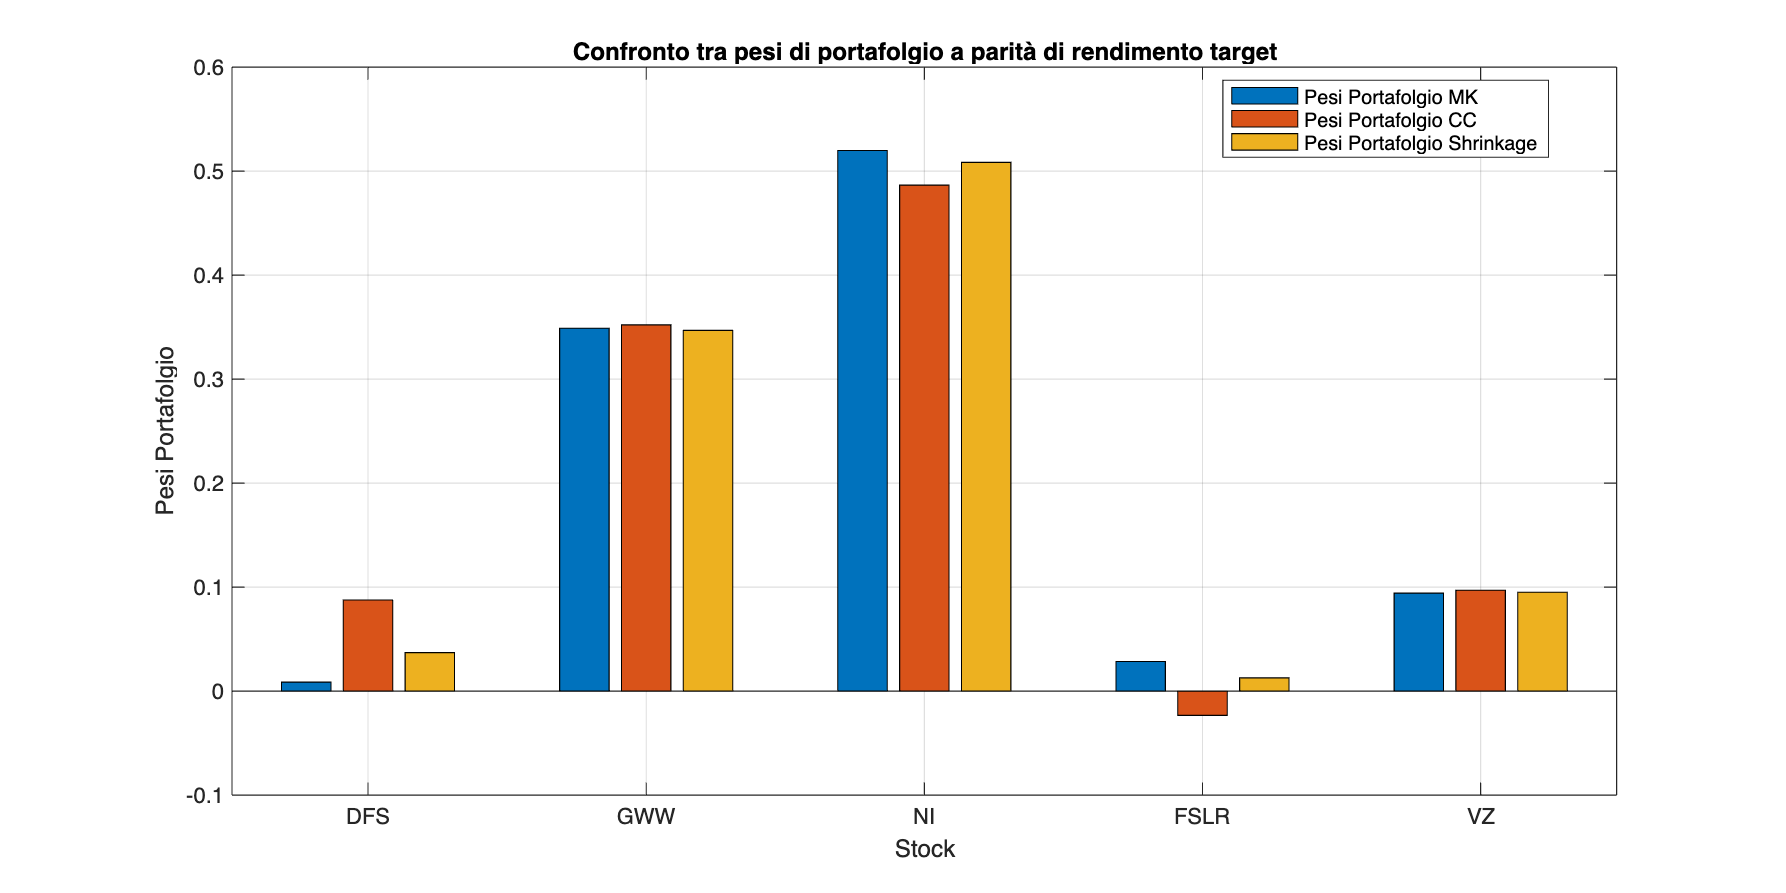

fig5 = figure('Position',[100,100,1600,800]);
bar_data = [w_opt, w_CC, w_shr];
bar(bar_data);
xticks(1:length(titoli)); 
xticklabels(titoli); 
legend({'Pesi Portafolgio MK', 'Pesi Portafolgio CC', 'Pesi Portafolgio Shrinkage'}, 'Location', 'best');
xlabel('Stock');
ylabel('Pesi Portafolgio');
title('Confronto tra pesi di portafolgio a parità di rendimento target');
grid on;

saveas(fig5,"img/Portafolgi_diverse_MTX.png")

## 2.2 Plotto la frontira ottima insieme ai portafolgi composti dai singoli titoli e il portafolgio w_MPV

mu_MVP = A/C;
m_inef = linspace(-0.1,A/C,100);
m_ef = linspace(A/C,0.1,100);

mu_MVP_CC = A_CC/C_CC;
m_inef_CC = linspace(-0.1,A_CC/C_CC,100);
m_ef_CC = linspace(A_CC/C_CC,0.1,100);

mu_MVP_shr = A_shr/C_shr;
m_inef_SCC = linspace(-0.1,A_shr/C_shr,100);
m_ef_SCC = linspace(A_shr/C_shr,0.1,100);                                   

Var_w = @(m) C/D*(m-A/C).^2+1/C;                                              
Var_w_CC = @(m) C_CC/D_CC*(m-A_CC/C_CC).^2+1/C_CC;
Var_w_SCC = @(m) C_shr/D_shr*(m-A_shr/C_shr).^2+1/C_shr;

blu_scuro = [0, 0.4470, 0.7410];
blu_chiaro = [0.6, 0.8, 1];

giallo_scuro =  [0.9290, 0.6940, 0.1250];
giallo_chiaro = [1.0000, 0.8500, 0.4000];

viola_scuro = [0.4940, 0.1840, 0.5560];
viola_chiaro = 	[0.8000, 0.6000, 0.9000];

fig6 = figure('Position',[100,100,1600,800])

fig6 =   Figure (8) with properties:

      Number: 8
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 1600 800]
       Units: 'pixels'

  Show all properties


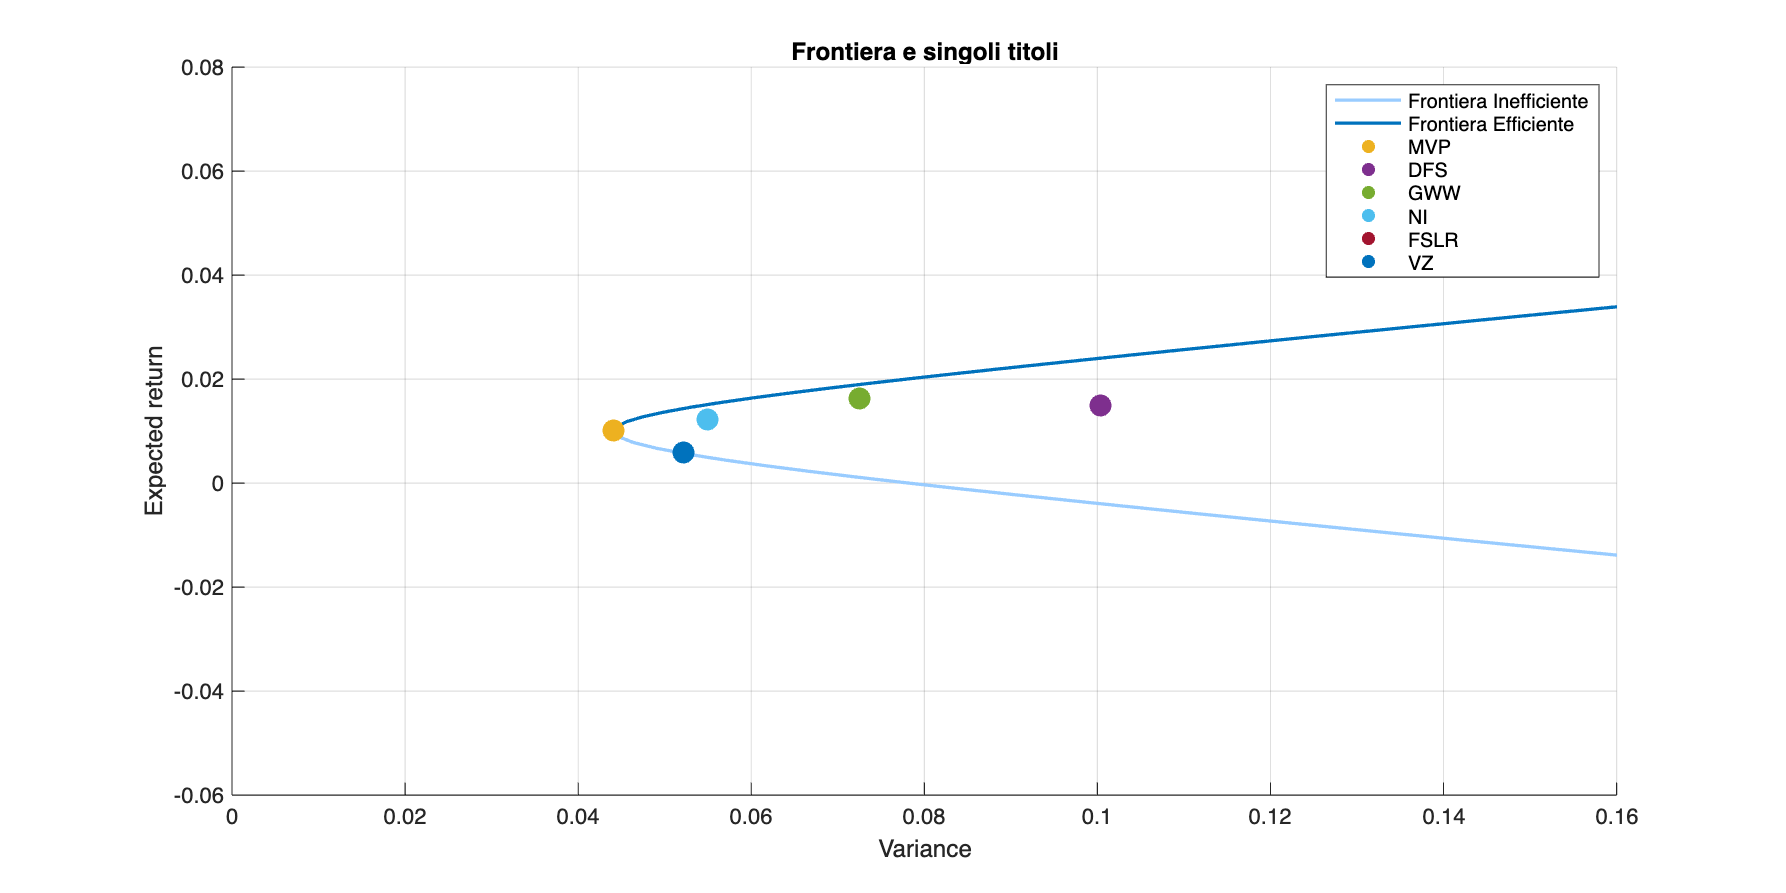

hold on

plot(sqrt(Var_w(m_inef)),m_inef ,'Color',blu_chiaro,'LineWidth', 1.5)
plot(sqrt(Var_w(m_ef)),m_ef ,'Color',blu_scuro,'LineWidth', 1.5)
scatter(sqrt(1/C),mu_MVP,100,'filled')

for i=1:1:5
scatter(sqrt(sigma(i,i)),mu(i),100,'filled')
end

legend(["Frontiera Inefficiente","Frontiera Efficiente","MVP",titoli]);
xlabel('Variance');
ylabel('Expected return');
grid on;
title("Frontiera e singoli titoli");
xlim([-0,0.16])
ylim([-0.06,0.08])

saveas(fig6,"img/Frontiera_MK.png")

## 3 Calcolo ANALITICO portafolgio tangente

risk_free_ann = 0.03;                                                      %annualizzato
risk_free = (1+risk_free_ann)^(1/12)-1;                                    %mensilizzato

w_tan = sigma\(mu-risk_free)/sum(sigma\(mu-risk_free));
mu_tan =  w_tan' * mu;
sigma_tan = (w_tan' * sigma * w_tan)

sigma_tan = 0.0035

CML = @(s) risk_free + (mu_tan-risk_free)*s/sqrt(sigma_tan)

CML = function_handle with value:
    @(s)risk_free+(mu_tan-risk_free)*s/sqrt(sigma_tan)


## Plot Portafolgio Tangente

fig7 = figure('Position',[100,100,1600,800])

fig7 =   Figure (9) with properties:

      Number: 9
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 1600 800]
       Units: 'pixels'

  Show all properties


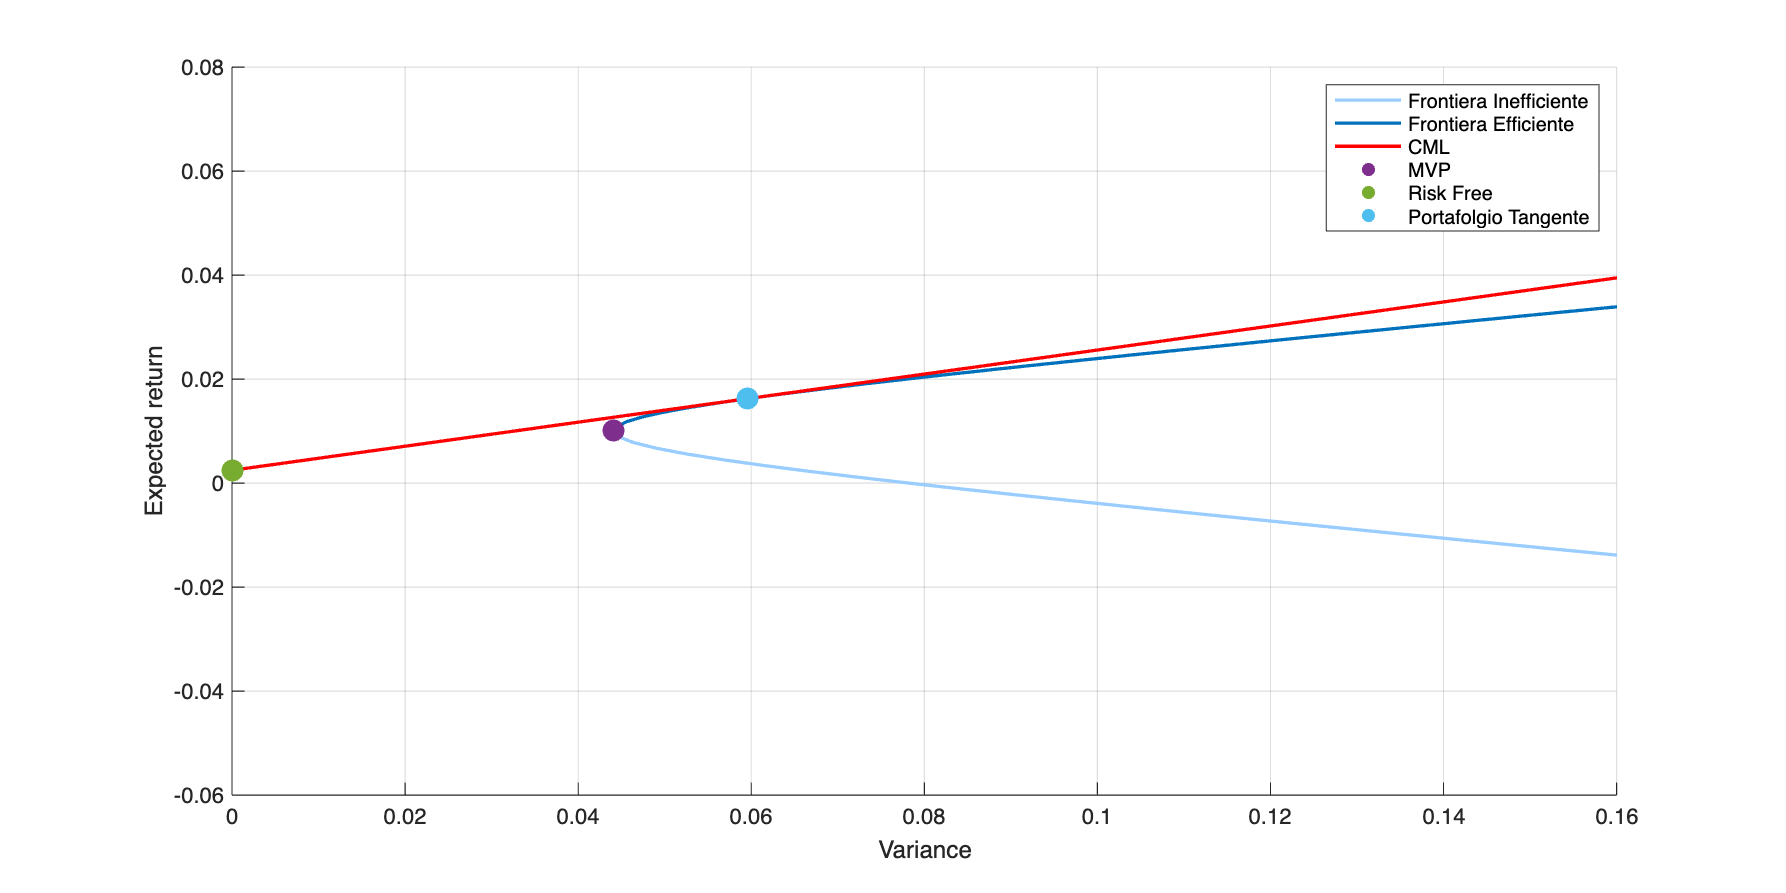

hold on
plot(sqrt(Var_w(m_inef)),m_inef ,'Color',blu_chiaro,'LineWidth', 1.5)
plot(sqrt(Var_w(m_ef)),m_ef ,'Color',blu_scuro,'LineWidth', 1.5)
s_ = linspace(0,0.5,100);
plot(s_ ,CML(s_),'Color','red','LineWidth', 1.5)
scatter(sqrt(1/C),mu_MVP,100,'filled')
scatter(0,risk_free,100,'filled')
scatter(sqrt(sigma_tan),mu_tan,100,'filled')
legend(["Frontiera Inefficiente","Frontiera Efficiente","CML","MVP","Risk Free","Portafolgio Tangente"]);
xlabel('Variance');
ylabel('Expected return');
grid on;
xlim([-0,0.16])
ylim([-0.06,0.08])
saveas(fig7,"img/Frontiera_risk_free.png")

## Plot Pesi dei portafogli in aggiunta il portafoglio tangente

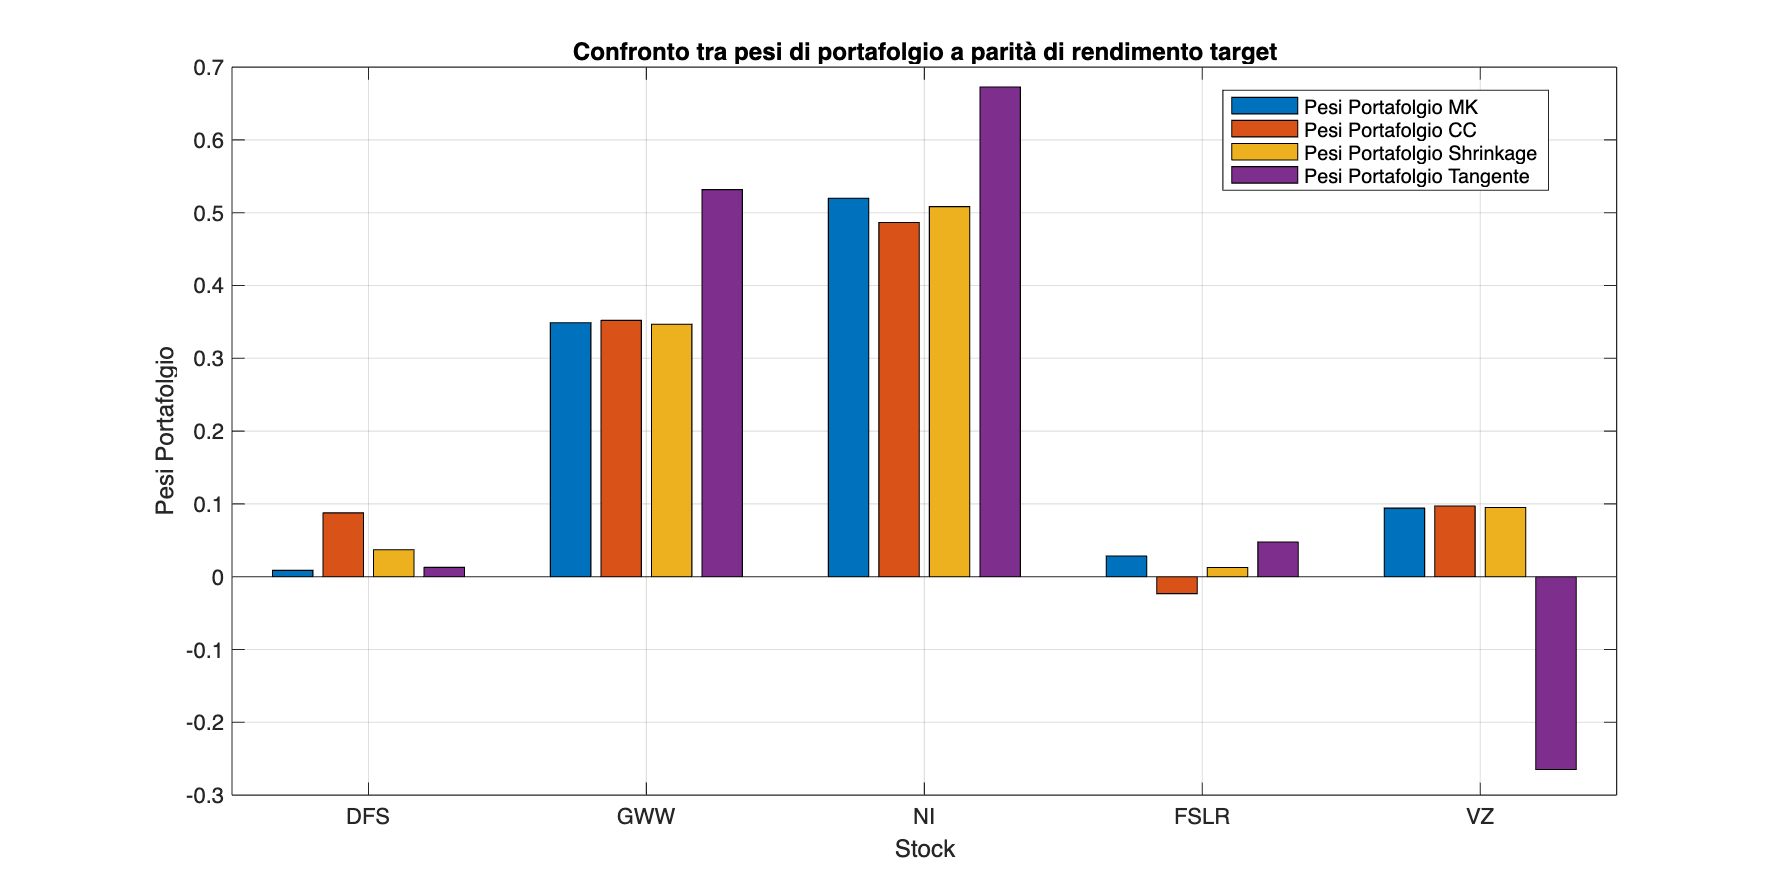

fig8 = figure('Position',[100,100,1600,800]);
bar_data = [w_opt, w_CC, w_shr,w_tan];
bar(bar_data);
xticks(1:length(titoli)); 
xticklabels(titoli); 
legend({'Pesi Portafolgio MK', 'Pesi Portafolgio CC', 'Pesi Portafolgio Shrinkage','Pesi Portafolgio Tangente'}, 'Location', 'best');
xlabel('Stock');
ylabel('Pesi Portafolgio');
title('Confronto tra pesi di portafolgio a parità di rendimento target');
grid on;
saveas(fig8,"img/Portafogli_con_tangente.png")

## CALCOLO PORTAFOLGIO TANGENTE (ANALITICO)

No vincoli

sharpe_ratio = @(w) (w' * mu-risk_free)/ sqrt(w' * sigma * w);

Aeq = ones(1,n_stock);
beq = 1;
lb = [];
ub = [];
x0 = ones(n_stock, 1) / n_stock; 
A = [];
b = [];
options = optimoptions('fmincon', 'Display', 'iter', 'Algorithm', 'sqp');
nonlcon = [];
w_tangente = fmincon(@(w) -sharpe_ratio(w),x0,A,b,Aeq,beq,lb,ub,nonlcon,options)

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           6   -1.784031e-01     0.000e+00     1.000e+00     0.000e+00     1.307e-01  
    1          12   -2.031684e-01     2.220e-16     1.000e+00     1.900e-01     5.970e-02  
    2          18   -2.134444e-01     2.220e-16     1.000e+00     1.555e-01     8.929e-02  
    3          24   -2.267276e-01     1.110e-16     1.000e+00     3.098e-01     4.367e-02  
    4          30   -2.286711e-01     2.220e-16     1.000e+00     6.841e-02     1.948e-02  
    5          36   -2.304474e-01     0.000e+00     1.000e+00     1.142e-01     1.511e-02  
    6          42   -2.310621e-01     0.000e+00     1.000e+00     7.906e-02     9.862e-03  
    7          48   -2.311825e-01     1.110e-16     1.000e+00     3.300e-02     3.572e-03  
    8          54   -2.312056e-01     2.220e-16     1.000e+00     8.870e-03     1.

w_tangente =     0.0128
    0.5317
    0.6726
    0.0476
   -0.2648


sigma_tangente = w_tangente' * sigma * w_tangente;
mu_tangente = w_tangente'* mu;

## CALCOLO PORTAFOLGIO TANGENTE (ANALITICO)

v1) Vincolo --> w1+w2 = 50%

Aeq = [ones(1,n_stock);[1,1,0,0,0]];
beq = [1,0.5];
lb = [];
ub = [];
x0 = ones(n_stock, 1) / n_stock; 
A = [];
b = [];
options = optimoptions('fmincon', 'Display', 'iter', 'Algorithm', 'sqp');
nonlcon = [];
w_tangentev1 = fmincon(@(w) -sharpe_ratio(w),x0,A,b,Aeq,beq,lb,ub,nonlcon,options)

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           6   -1.784031e-01     1.000e-01     1.000e+00     0.000e+00     1.307e-01  
    1          12   -2.031754e-01     0.000e+00     1.000e+00     1.897e-01     5.988e-02  
    2          18   -2.137193e-01     1.110e-16     1.000e+00     1.508e-01     7.818e-02  
    3          24   -2.267811e-01     2.220e-16     1.000e+00     3.182e-01     4.544e-02  
    4          30   -2.286254e-01     1.110e-16     1.000e+00     6.427e-02     2.169e-02  
    5          36   -2.300800e-01     3.331e-16     1.000e+00     9.232e-02     1.500e-02  
    6          42   -2.308181e-01     2.220e-16     1.000e+00     8.169e-02     1.009e-02  
    7          48   -2.309885e-01     5.551e-17     1.000e+00     3.570e-02     6.123e-03  
    8          54   -2.310063e-01     2.220e-16     1.000e+00     6.677e-03     1.

w_tangentev1 =     0.0043
    0.4957
    0.6824
    0.0490
   -0.2314


sigma_tangentev1 = w_tangentev1'*sigma*w_tangentev1;
mu_tangentev1 = w_tangentev1'* mu;

## CALCOLO PORTAFOLGIO TANGENTE (ANALITICO)

v2) Vincolo --> lower bound w = 10% (posizioni long di almeno il 10%)

Aeq = ones(1,n_stock);
beq = 1;
lb = 0.1*ones(1,n_stock);
ub = [];
x0 = ones(n_stock, 1) / n_stock; 
A = [];
b = [];
options = optimoptions('fmincon', 'Display', 'iter', 'Algorithm', 'sqp');
nonlcon = [];
w_tangentev2 = fmincon(@(w) -sharpe_ratio(w),x0,A,b,Aeq,beq,lb,ub,nonlcon,options)

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           6   -1.784031e-01     0.000e+00     1.000e+00     0.000e+00     1.307e-01  
    1          12   -2.010680e-01     0.000e+00     1.000e+00     1.424e-01     5.579e-02  
    2          18   -2.116973e-01     2.220e-16     1.000e+00     1.328e-01     5.163e-02  
    3          24   -2.137399e-01     2.220e-16     1.000e+00     4.117e-02     1.318e-02  
    4          30   -2.137721e-01     2.220e-16     1.000e+00     6.052e-03     3.548e-03  
    5          36   -2.138280e-01     2.220e-16     1.000e+00     2.417e-02     2.568e-04  
    6          42   -2.138281e-01     2.220e-16     1.000e+00     6.119e-04     5.230e-06  
    7          48   -2.138281e-01     2.220e-16     1.000e+00     1.144e-05     3.514e-09  

Local min

w_tangentev2 =     0.1000
    0.3410
    0.3590
    0.1000
    0.1000


sigma_tangentev2 = w_tangentev2'*sigma*w_tangentev2;
mu_tangentev2 = w_tangentev2'* mu;

## PLOT DEI PESI DEI DIVERSI PORTAFOLGIO TANGENTI

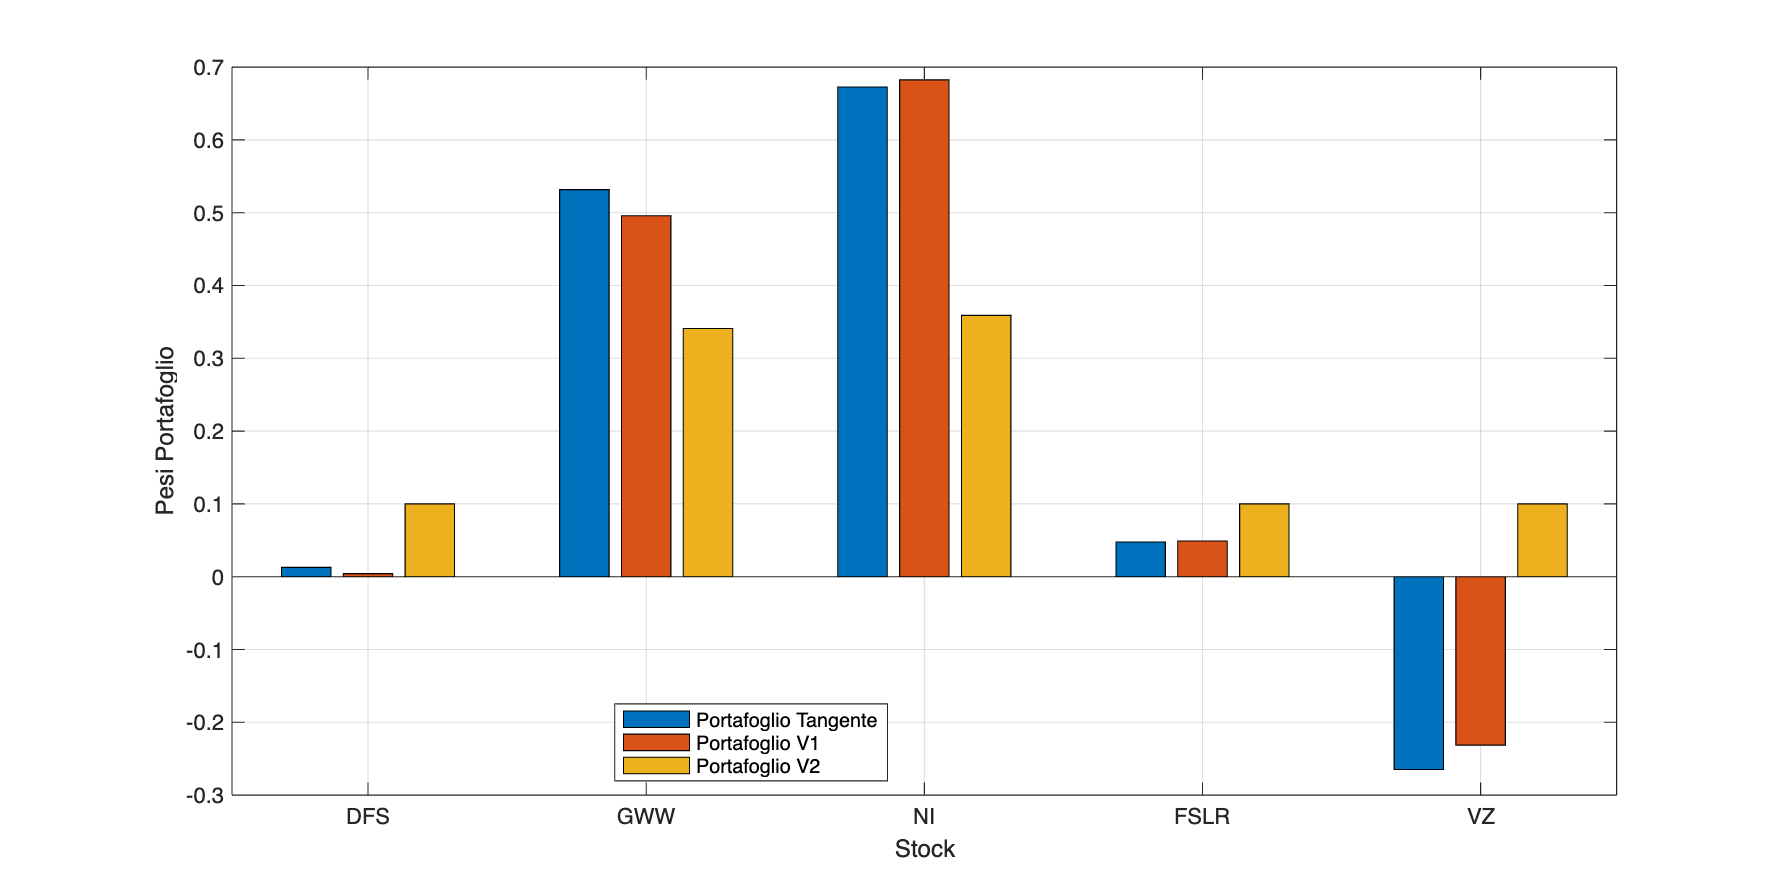

fig10 = figure('Position', [100, 100, 1600, 800]);

bar_data = [w_tangente, w_tangentev1, w_tangentev2];
n_stocks = size(bar_data, 1); 
n_portfolios = size(bar_data, 2); 
b = bar(bar_data, 'grouped'); 
xticks(1:n_stocks);
xticklabels(titoli); 
legend({'Portafoglio Tangente', 'Portafoglio V1', 'Portafoglio V2'}, 'Location', 'best');
xlabel('Stock');
ylabel('Pesi Portafoglio');
grid on;

saveas(fig10, "img/Pesi Portafolgi risk free vincolati.png")

## CALCOLO PORTAFOLGIO DI FRONTIERA

No vincoli

mu_target = 0.5/100;
H = 2 * sigma;
f = [];
A = [];
b = [];
lb = [];     
ub = [];

Aeq = [(mu-risk_free)'];
j = 1;
for m = linspace(risk_free,0.1,100)
beq = [m-risk_free];
w0 = (m-risk_free)/(sigma\(mu-risk_free));
[w(:,j),variance(j)] = quadprog(H,f,A,b,Aeq,beq,lb,ub);
mu_risky = w(:,j)' * mu;
lambda(j) = (m-risk_free)/(mu_risky-risk_free);
j = j+1;
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because


mu_frontiera_libera = sum(w.*mu) + (1-sum(w))*risk_free; %sum(w.*mu.*lambda) + (1-lambda)*risk_free;

% Portafolgio target per mu_target = 0.5/100
beq = [mu_target-risk_free];
w0 = (mu_target-risk_free)/(sigma\(mu-risk_free));
[w_target_free,variance_target_free] = quadprog(H,f,A,b,Aeq,beq,lb,ub);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


mu_target_free = w_target_free' * mu;
per_free_risk = 1-sum(w_target_free)

per_free_risk = 0.8159

mu_tot_free = mu_target_free + per_free_risk*risk_free;

## CALCOLO PORTAFOLGIO DI FRONTIERA

V1) w1+w2 = 50%

Aeq = [(mu-risk_free)';[1,1,0,0,0]];
j = 1;
for m = linspace(risk_free,0.1,100)
beq = [m-risk_free;0.5];
w0 = (m-risk_free)/(sigma\(mu-risk_free));
[w1(:,j),variance1(j)] = quadprog(H,f,A,b,Aeq,beq,lb,ub);
mu_risky = w1(:,j)' * mu;
lambdav1(j) = (m-risk_free)/(mu_risky-risk_free);
j = j+1;
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because


mu_frontierav1 = sum(w1.*mu) + (1-sum(w1))*risk_free; %sum(w1.*mu.*lambdav1) + (1-lambdav1)*risk_free;

% Portafolgio target per mu_target = 0.5/100
mu_target = 0.5/100;
beq = [mu_target-risk_free;0.5];
w0 = (mu_target-risk_free)/(sigma\(mu-risk_free));
[w_target_v1,variance_target_v1] = quadprog(H,f,A,b,Aeq,beq,lb,ub);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


mu_target_v1 = w_target_v1' * mu;
lambdav1 = (mu_target-risk_free)/(mu_risky-risk_free)

lambdav1 = 0.0219

per_free_risk = 1-sum(w_target_v1)

per_free_risk = 0.9779

mu_tot_v1 = mu_target_v1 + per_free_risk*risk_free;

## CALCOLO PORTAFOLGIO DI FRONTIERA

V2) Vincolo --> lower bound w = 10% (posizioni long di almeno il 10%)

Aeq = [(mu-risk_free)'];  
lb = 0.1*ones(1,n_stocks);                                               
j = 1;
for m = linspace(0.008,0.1,100)
beq = [m-risk_free];
w0 = (m-risk_free)/(sigma\(mu-risk_free));
[w2(:,j),variance2(j)] = quadprog(H,f,A,b,Aeq,beq,lb,ub);
mu_risky = w2(:,j)' * mu;
lambdav2(j) = (m-risk_free)/(mu_risky-risk_free);
j = j+1;
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because


mu_frontierav2 = sum(w2.*mu) + (1-sum(w2))*risk_free; %sum(w2.*mu.*lambdav2) + (1-lambdav2)*risk_free;

% Portafolgio target per mu_target = 0.5/100
beq = [mu_target-risk_free];
w0 = (mu_target-risk_free)/(sigma\(mu-risk_free));
[w_target_v2,variance_target_v2] = quadprog(H,f,A,b,Aeq,beq,lb,ub);


The problem is infeasible.

During presolve, quadprog found the constraints to be inconsistent 
to within the constraint tolerance.



## PLOT DELLE FRONTIERE VINCOLATE CON I RELATIVI PORTFOLGI TANGENTI E RENDIMENTO TARGET 0.5%

fig11 = figure('Position',[100,100,1800,300])

fig11 =   Figure (12) with properties:

      Number: 12
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [100 100 1800 300]
       Units: 'pixels'

  Show all properties


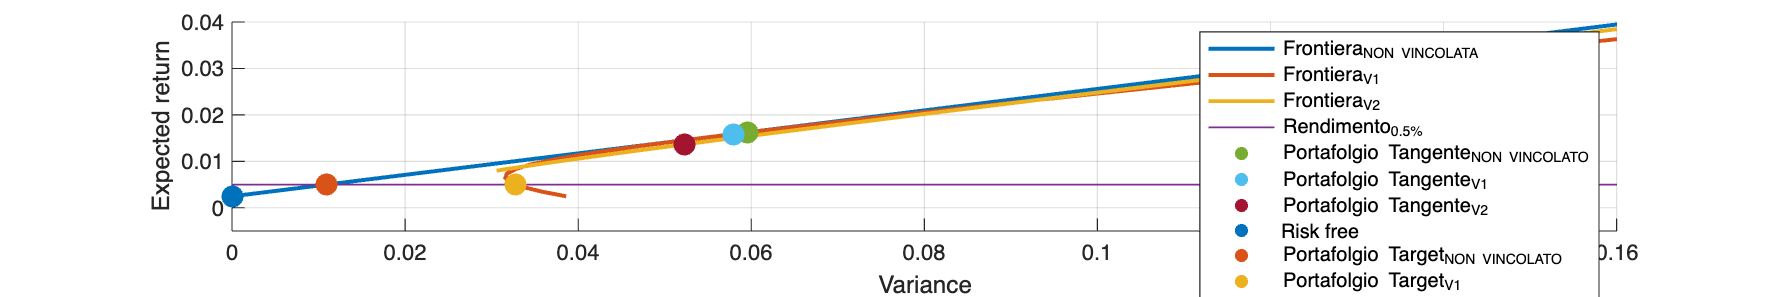

hold on
plot(sqrt(variance),mu_frontiera_libera,"LineWidth",1.8)
plot(sqrt(variance1),mu_frontierav1,"LineWidth",1.8)
plot(sqrt(variance2),mu_frontierav2,"LineWidth",1.8)
plot([0,0.18],[mu_target,mu_target],"LineWidth",0.8)
scatter(sqrt(sigma_tan),mu_tan,100,'filled')
scatter(sqrt(sigma_tangentev1),mu_tangentev1,100,'filled')
scatter(sqrt(sigma_tangentev2),mu_tangentev2,100,'filled')
scatter(0,risk_free,100,'filled')
scatter(sqrt(variance_target_free),mu_tot_free,100,'filled')
scatter(sqrt(variance_target_v1),mu_tot_v1,100,'filled')
legend(["Frontiera_{NON VINCOLATA}","Frontiera_{V1}","Frontiera_{V2}","Rendimento_{0.5%}","Portafolgio Tangente_{NON VINCOLATO}","Portafolgio Tangente_{V1}","Portafolgio Tangente_{V2}","Risk free","Portafolgio Target_{NON VINCOLATO}","Portafolgio Target_{V1}"]);
xlabel('Variance');
ylabel('Expected return');
grid on;
xlim([-0,0.16])
ylim([-0.005,0.04])
saveas(fig11, "img/Frontiere vincolate.png")

## CAPM

Calcolo dei valori di alpha e beta tramite regressione lineare con i rendimenti spx e con rf = 0.02

rf = 0.02

rf = 0.0200

for i=1:n_stocks
    lm=fitlm(spx_returns-rf,returns(2:end,i)-rf);
    alpha(i)=lm.Coefficients.Estimate(1);
    beta(i)=lm.Coefficients.Estimate(2);
    p_value_alpha = lm.Coefficients.pValue(1);     % p-value di alpha
    significant_alpha(i) = (p_value_alpha < 0.05); % True se significativo
    %returns_pred(:,i)=risk_free+(spx_returns-risk_free)*beta(i)
end